% Iqbal Luqmanul Hakim 
% 082111733063
clc; clear all;

x = [0.5 1.0 1.5 2.0 2.5];
y = [0.49 1.60 3.36 6.44 10.16];

jumx = 0;
jumxx = 0;
jumy = 0;
jumxy = 0;

for i = 1:5
    jumx = jumx + x(i);
    jumxx = jumxx + (x(i) ^ 2);
    jumy = jumy + y(i);
    jumxy = jumxy + (y(i) * x(i));
end

A = [5 jumx; jumx jumxx];
B = [jumy; jumxy];

C = inv(A) * B;

disp('Tabel Nilai:');

Tabel Nilai:


disp('------------------------------------------------------------------');

------------------------------------------------------------------


disp('   x    |    y    |   ln(x)  |   ln(y)  | ln(x)*ln(y) | (ln(x))^2');

   x    |    y    |   ln(x)  |   ln(y)  | ln(x)*ln(y) | (ln(x))^2


disp('------------------------------------------------------------------');

------------------------------------------------------------------


for i = 1:5
    ln_x = log(x(i));
    ln_y = log(y(i));
    ln_xy = ln_x * ln_y;
    ln_x_squared = ln_x^2;
    disp([x(i), y(i), ln_x, ln_y, ln_xy, ln_x_squared]);
end

    0.5000    0.4900   -0.6931   -0.7133    0.4945    0.4805

    1.0000    1.6000         0    0.4700         0         0

    1.5000    3.3600    0.4055    1.2119    0.4914    0.1644

    2.0000    6.4400    0.6931    1.8625    1.2910    0.4805

    2.5000   10.1600    0.9163    2.3185    2.1244    0.8396



disp('------------------------------------------------------------------');

------------------------------------------------------------------


disp(['JumX  = ', num2str(jumx)]);

JumX  = 7.5


disp(['JumXY = ', num2str(jumxy)]);

JumXY = 45.165


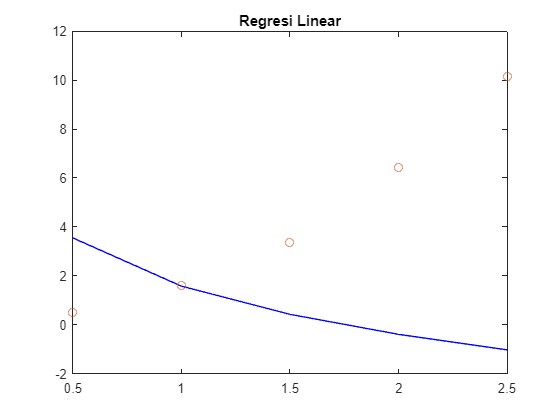


ln_f = zeros(1, 5); % Inisialisasi array untuk menyimpan nilai ln(f(x))

for i = 1:5
    ln_f(i) = log(C(2)) + C(1) * log(x(i)); % Menggunakan rumus ln(f(x)) = ln(a) + b*ln(x)
end

plot(x, ln_f, 'b', x, y, 'o');
title('Regresi Linear');